begin = 1;
ending = 4;
x = linspace(begin, ending, 100);
fun = @(t) sin(t);


Рунге

for n = 10:1:100
    x_testrh = linspace(begin, ending , n);
    x_testrh2 = linspace(begin, ending , 2*n);
    h = x_testrh(2)-x_testrh(1);
    h2 = x_testrh2(2)-x_testrh2(1);
    
    int_h = left_rectangle(x_testrh, fun);
    int_h2 = left_rectangle(x_testrh2, fun);
    
    C1(n) = ((int_h2-int_h)/(h^1-h2^1));
end

for n = 10:1:100
    x_testrh = linspace(begin, ending , n);
    x_testrh2 = linspace(begin, ending , 2*n);
    h = x_testrh(2)-x_testrh(1);
    h2 = x_testrh2(2)-x_testrh2(1);
    
    int_h = mid_rectangle(x_testrh, fun);
    int_h2 = mid_rectangle(x_testrh2, fun);
    
    C2(n) = ((int_h2-int_h)/(h^2-h2^2));
end

for n = 10:1:100
    x_testrh = linspace(begin, ending , n);
    x_testrh2 = linspace(begin, ending , 2*n);
    h = x_testrh(2)-x_testrh(1);
    h2 = x_testrh2(2)-x_testrh2(1);
    
    int_h = trapezoid(x_testrh, fun);
    int_h2 = trapezoid(x_testrh2, fun);
    
    C3(n) = ((int_h2-int_h)/(h^2-h2^2));
end

for n = 10:1:100
    x_testrh = linspace(begin, ending , n);
    x_testrh2 = linspace(begin, ending , 2*n);
    h = x_testrh(2)-x_testrh(1);
    h2 = x_testrh2(2)-x_testrh2(1);
    
    int_h = Simpson(x_testrh, fun);
    int_h2 = Simpson(x_testrh2, fun);
    
    C4(n) = ((int_h2-int_h)/(h^3-h2^3));
end


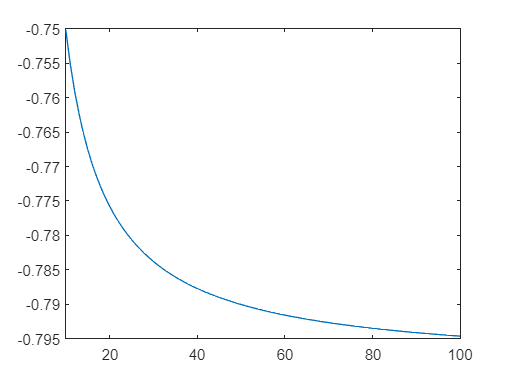

plot(C1)
xlim([10 100])

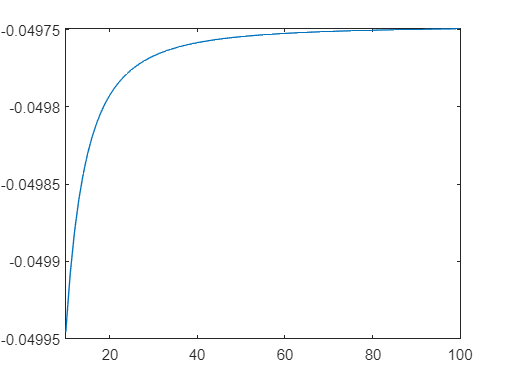

plot(C2)
xlim([10 100])

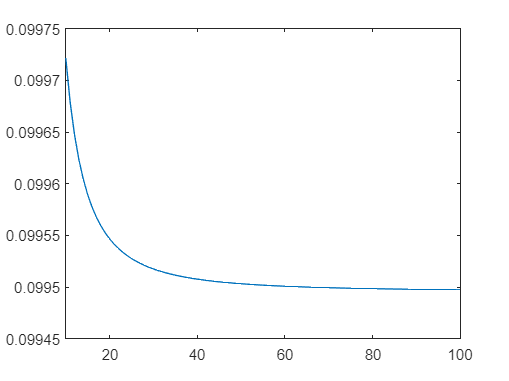

plot(C3)
xlim([10 100])

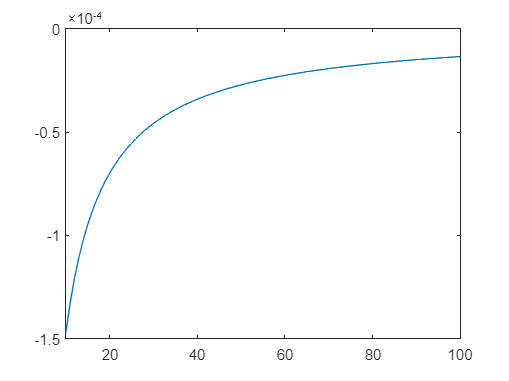

plot(C4)
xlim([10 100])